# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, 1 output, 0 input
statenum = 100

statenum = 100


state_space = drss(statenum,1,0);
A = state_space.A

A =    -1.6229    0.2326    1.1216    0.6696    0.7414    0.8192   -0.0780    0.2343    2.2898   -0.6535    2.1508    0.4453   -2.7676   -0.1882    2.2800    0.0185   -1.4490    0.8470   -1.4595   -0.6954   -0.4945    1.1495   -1.3176   -0.5607    0.0611    1.3247    0.5564    0.5057    0.3084   -1.0037    0.8590    1.5512    1.5023   -0.5447   -0.8983   -0.5766   -0.1528   -0.8305    0.8828    0.0785    0.1372   -0.8347   -1.7413    0.9813   -0.7733    0.1614   -0.3167   -0.9759   -0.0720   -0.8056
    1.3173   -1.1685   -1.9510   -0.6390   -0.8414   -0.8057   -0.6492   -0.6202   -2.6869    0.9579   -1.6069   -0.5906    2.9680   -0.2188   -2.0068   -0.7087    0.8628   -0.3516    0.9401    0.6529    0.3098   -1.4095    0.6530    0.7914   -0.4612   -1.5203    0.3490   -0.5836    0.0548    0.4614   -1.0104   -1.4691   -1.3035    0.6578    1.4884    1.0993   -0.1082    1.0513   -0.5050    0.1187   -0.3726    0.7292    1.4516   -0.8831    0.3891   -0.4478    0.0696    1.2171   -0.1776    0

C = state_space.C

C =    -0.4496   -0.9312    1.1810    1.0243    0.5741    0.3142    0.0315    1.4427   -0.2238   -2.0665         0   -0.6388         0   -1.8089   -1.4169   -1.4598         0   -1.1933   -0.1335    0.3799    0.9109    1.6776         0         0    1.7241    0.2576         0   -1.5316   -0.6906   -0.4516   -0.4704   -1.8027    0.5989    2.3193   -0.3413         0    0.4908         0         0   -1.2519   -0.2337    0.9257   -1.3403         0    1.3197   -0.2719   -0.2470   -1.4399         0   -1.1849



abs(eig(A))

ans =     0.9737
    0.9737
    0.9837
    0.9837
    0.9080
    0.8985
    1.0000
    0.9924
    0.8174
    0.8174


Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

interval = 100;

x = zeros(statenum,interval);
y = zeros(1,interval);
x(:,1) = rand(statenum,1);
y(:,1) = C*x(:,1)

y =    -2.4131         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


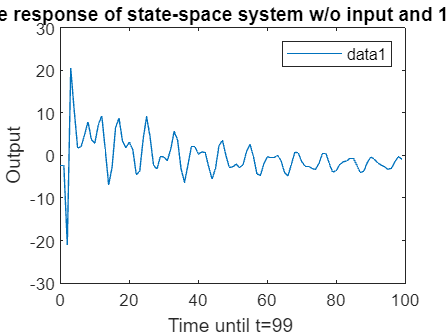


for i=2:interval
    y(:,i) = C*x(:,i-1);
    x(:,i) = A*x(:,i-1);
end



plot(0:interval-1,y)
xlabel("Time until t="+ (interval-1)+" ");
ylabel("Output");
title("Impulse response of state-space system w/o input and "+ statenum+ " states");
legend('show');

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither nor unstable (marginally stable).

## Experimenting with LTI's with input

## Experimenting with Hankel Matrices

## Experimenting with Hankel Matrix Completion